# Data Analysis

## Piano inclinato

% cleaning
clc
clear

% importing data
df1=readtable("experimental-data-1.csv")

df1 = 9×4 table
    grandezza    valore    incertezza     udm 
    _________    ______    __________    _____

     {'h2'}      0.412       0.001       {'m'}
     {'h1'}      1.122       0.001       {'m'}
     {'s1'}      1.992       0.001       {'m'}
     {'s2'}      0.713       0.001       {'m'}
     {'m1'}      15.19        0.01       {'g'}
     {'m2'}      98.82        0.01       {'g'}
     {'m3'}      130.6        0.01       {'g'}
     {'m4'}      13.79        0.01       {'g'}
     {'m5'}       26.6        0.01       {'g'}


df2=readtable("experimental-data-2.csv")

df2 = 200×5 table
    index    massa      t      inertezza     udm 
    _____    ______    ____    _________    _____

      1      {'m1'}    1.65      0.01       {'s'}
      2      {'m1'}     1.6      0.01       {'s'}
      3      {'m1'}    1.66      0.01       {'s'}
      4      {'m1'}    2.18      0.01       {'s'}
      5      {'m1'}    1.54      0.01       {'s'}
      6      {'m1'}    1.74      0.01       {'s'}
      7      {'m1'}    1.47      0.01       {'s'}
      8      {'m1'}    1.55      0.01       {'s'}
      9      {'m1'}     1.8      0.01       {'s'}
     10      {'m1'}    1.75      0.01       {'s'}
     11      {'m1'}    1.94      0.01       {'s'}
     12      {'m1'}    2.05      0.01       {'s'}
     13      {'m1'}    2.67      0.01       {'s'}
     14      {'m1'}    1.56      0.01       {'s'}
     15    

tools=readtable("tools.csv")

tools = 3×3 table
       Strumento       Sensibilita     udm 
    _______________    ___________    _____

    {'Flessometro'}       0.001       {'m'}
    {'Bilancia'   }        0.01       {'g'}
    {'Cronometro' }        0.01       {'s'}


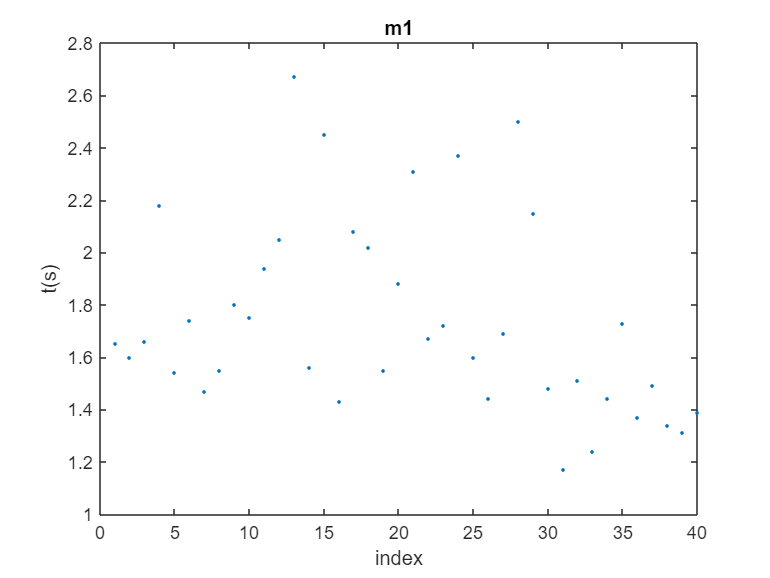

% incertezza
ds=tools.Sensibilita(1);
dt=tools.Sensibilita(3);

% tempi
t=df2.t;
t1=t(1:40,:);
%histfit(t1m1)
%hist(tm1)

t2=df2.t(41:80,:);
%hist(tm2)

t3=df2.t(81:120,:);
%hist(tm3)

t4=df2.t(121:160,:);
%hist(tm4)

t5=df2.t(161:200,:);
%hist(tm5)

% average time
tm1=mean(t1);
tm2=mean(t2);
tm3=mean(t3);
tm4=mean(t4);
tm5=mean(t5);

% creating array
tm=[tm1,tm2,tm3,tm4,tm5];

% space
s1=df1.valore(3);
s2=df1.valore(4);
s=s1-s2;

% height
h2=df1.valore(1);
h1=df1.valore(2);
h=h1-h2;

% angle
rteta=asin(h./s); %rad
dteta=(180./pi)*rteta; %deg

% plotting times
figure
plot(1:40,t1,".")
title('m1')
ylabel('t(s)')
xlabel('index')

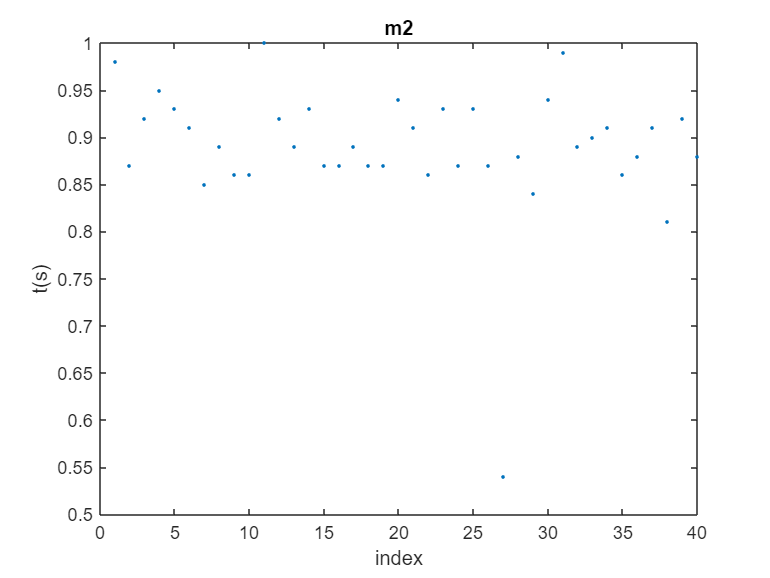


figure
plot(1:40,t2,".")
title('m2')
ylabel('t(s)')
xlabel('index')

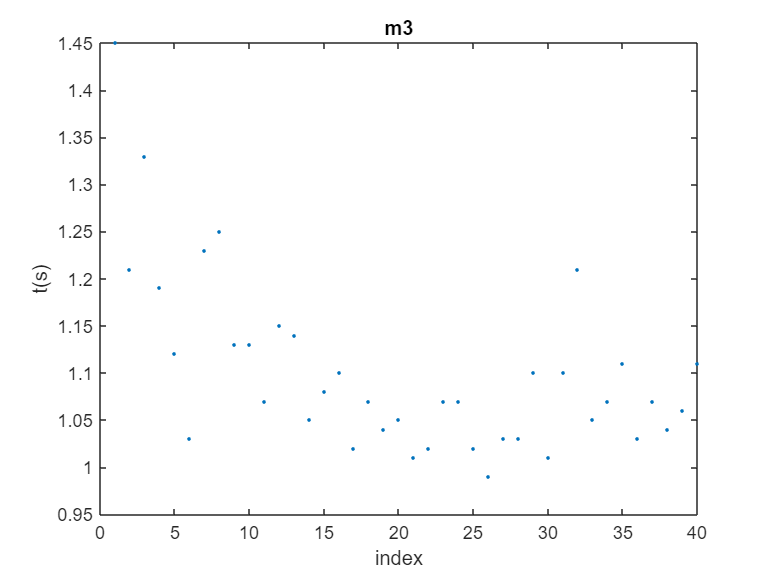


figure
plot(1:40,t3,".")
title('m3')
ylabel('t(s)')
xlabel('index')

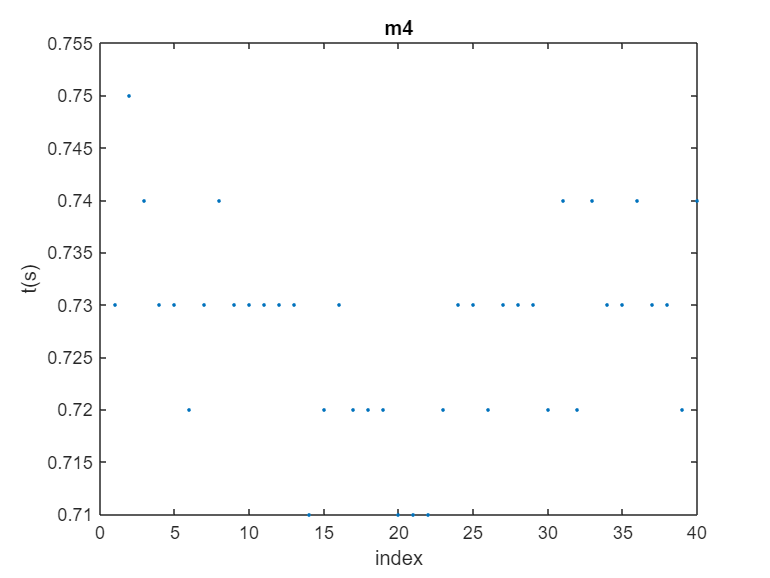


figure
plot(1:40,t4,".")
title('m4')
ylabel('t(s)')
xlabel('index')

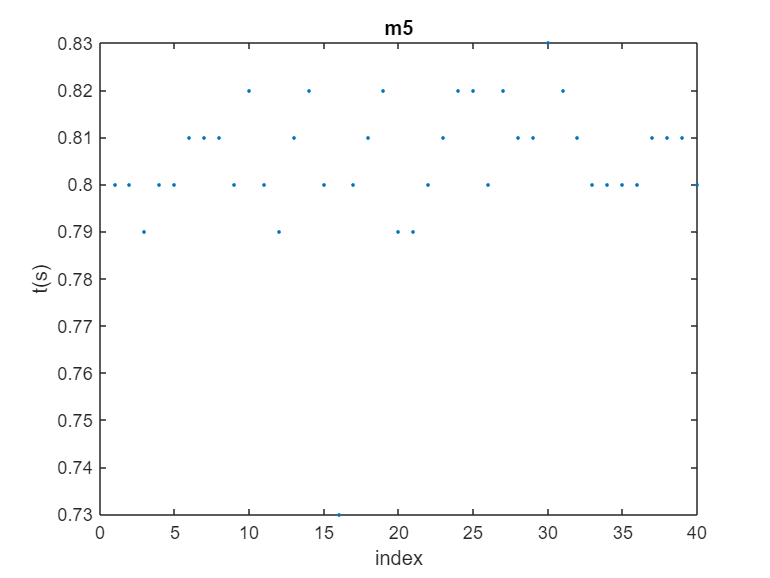


figure
plot(1:40,t5,".")
title('m5')
ylabel('t(s)')
xlabel('index')


% subplot
% subplot(5,1,1)
% plot(1:40,tm1,".")
% title('m1')
% ylabel('t(s)')
% xlabel('index')
% subplot(5,1,2)
% plot(1:40,tm2,".")
% title('m2')
% ylabel('t(s)')
% xlabel('index')
% subplot(5,1,3)
% plot(1:40,tm3,".")
% title('m3')
% ylabel('t(s)')
% xlabel('index')
% subplot(5,1,4)
% plot(1:40,tm4,".")
% title('m4')
% ylabel('t(s)')
% xlabel('index')
% subplot(5,1,5)
% plot(1:40,tm5,".")
% title('m5')
% ylabel('t(s)')
% xlabel('index')

% test calculating g
g1=(2.*s)/(sin(rteta).*((mean(t1)).^2))

g1 = 1.5268

g2=(2.*s)/(sin(rteta).*((mean(t2)).^2))

g2 = 5.8207

g3=(2.*s)/(sin(rteta).*((mean(t3)).^2))

g3 = 3.8014

g4=(2.*s)/(sin(rteta).*((mean(t4)).^2))

g4 = 8.7066

g5=(2.*s)/(sin(rteta).*((mean(t5)).^2))

g5 = 7.1197


% acceleration
a=zeros(length(tm),1);
da=zeros(length(tm),1);
rea=zeros(length(tm),1);

for i=1:length(tm)
    a(i)=(2.*s)/((tm(i)).^2);
    da(i)=(2.*(ds+(4.*s.*dt)))./(tm(i).^2);
    rea(i)=(da(i)/a(i))*100;
end

% c'è qualcosa che non va nell'errore relativo dell'accelerazione?

horzcat(a,da,rea)

ans =     0.8476    0.0346    4.0782
    3.2312    0.1318    4.0782
    2.1102    0.0861    4.0782
    4.8332    0.1971    4.0782
    3.9523    0.1612    4.0782



% propagazione errori
dg= 0.01;
g=9.81;
n=length(t1);

% creating empty array
dmu=zeros(length(tm),1);
mu=zeros(length(tm),1);
rec=zeros(length(tm),1); % relative error
cfr=zeros(length(tm),1);
cfra=zeros(length(tm),1);

% calculating dmu and mu
for i=1:length(tm)
    dmu(i)=(((2.*ds)/(((cos(rteta)).^2)*sqrt(s.^2-h^2))).*(1-((a(i).*sin(rteta))./g)).*(1+(h./s)))+((2.*(ds+(4.*s.*dt)))./((tm(i).^2).*g.*cos(rteta)))+((a(i).*dg)./((g.^2).*cos(rteta)));
    mu(i)=tan(rteta)-(a(i)./g.*cos(rteta));
    rec(i)=(dmu(i)./mu(i))*100;

    % rounding 
    cfr(i)=-floor(log10(dmu(i)));
    dmu(i)=round(dmu(i),cfr(i));
    mu(i)=round(mu(i),cfr(i));
    rec(i)=round(rec(i),2);
    cfra(i)=-floor(log10(da(i)));
    da(i)=round(da(i),cfra(i));
    a(i)=round(a(i),cfra(i));
    rea(i)=round(rea(i),2);
end

% creating output array
acceleration=string(horzcat(a,da,rea))

acceleration = 5×3 string array
    "0.85"    "0.03"    "4.08"
    "3.2"     "0.1"     "4.08"
    "2.11"    "0.09"    "4.08"
    "4.8"     "0.2"     "4.08"
    "4"       "0.2"     "4.08"


coefficient=string(horzcat(mu,dmu,rec))

coefficient = 5×3 string array
    "0.596"    "0.008"    "1.4" 
    "0.39"     "0.02"     "5.09"
    "0.49"     "0.01"     "2.97"
    "0.26"     "0.03"     "10.8"
    "0.33"     "0.02"     "7.08"


% correggere cifre significative output

% exporting csv
writetable(array2table(acceleration,'VariableNames',{'accelerazione','incertezza','errore_relativo'}),'output-data-1.csv','Delimiter',',','Encoding','UTF-8')
writetable(array2table(coefficient,'VariableNames',{'coefficiente_attrito','incertezza','errore_relativo'}),'output-data-2.csv','Delimiter',',','Encoding','UTF-8')

% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);